## Streamlines and the Streamfunction

clc, close all, clear

## Example 1: Horizontal flow (homogeneous)

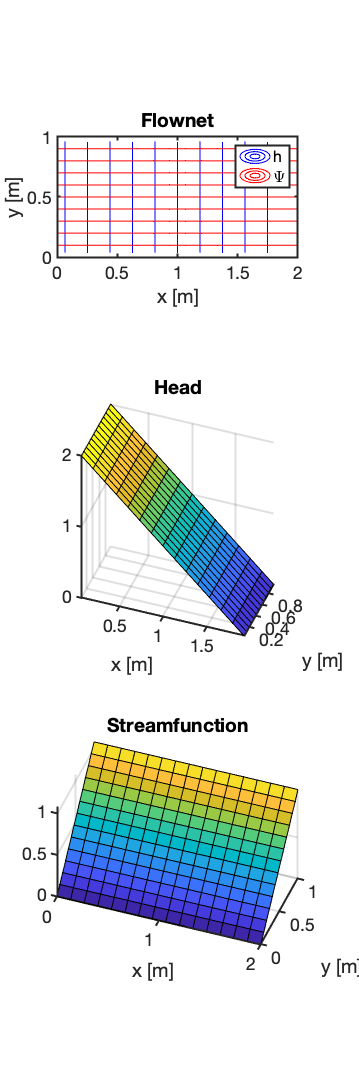

% Numerical grid
Grid.xmin = 0; Grid.xmax = 2;  Grid.Nx = 15;
Grid.ymin = 0; Grid.ymax = 1;  Grid.Ny = 13;
Grid = build_grid(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[Xp,Yp] = meshgrid(Grid.xf,Grid.yf);

% Discrete operators
[D,G,~,I,M] = build_ops(Grid);
L = -D*G; fs = sparse(Grid.N,1);
Kd = 1;
flux = @(h) -Kd*G*h;
res = @(h,cell) L(cell,:)*h-fs(cell);

% Boundary conditions
BC.dof_dir   = [Grid.dof_xmin;   Grid.dof_xmax]; 
BC.dof_f_dir = [Grid.dof_f_xmin; Grid.dof_f_xmax]; 
BC.g         = [2*ones(Grid.Ny,1); zeros(Grid.Ny,1)];
BC.dof_neu   = []; 
BC.dof_f_neu = [];
BC.qb = [];

% Build boundary operators
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve system
h = solve_lbvp(L,fs+fn,B,BC.g,N); 
q = comp_flux_gen(flux,res,h,Grid,BC);%(D,Kd,G,h,fs,Grid,BC);
%% Compute streamfunction
% [Xp,Yp] = meshgrid(Grid.xf,Grid.yf);

Grid.psi_x0 = 'xmin_ymin'; Grid.psi_dir = 'xy';
[PSI, psi_min1, psi_max1] = comp_streamfun(q,Grid);


figure('position',[10 10 500 1500])
subplot 311
plot_flownet(11,11,h,PSI,'b-','r',Grid), hold on
% plot(0,0,'ro','markerfacecolor','r','markersize',12)
% plot([0 Grid.xmax],[0 0],'r-','linewidth',5)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Flownet'
legend('h','\Psi')

subplot 312
surf(Xc,Yc,reshape(h,Grid.Ny,Grid.Nx)), view(20,40)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Head'


subplot 313
surf(Xp,Yp,PSI), view(20,40)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Streamfunction'

### Path independence of the streamfunction

If the velocity/flux field is divergence free then the streamfunction is independent of the integration path. However we can choose different reference points, which introduces and arbitrary constant.

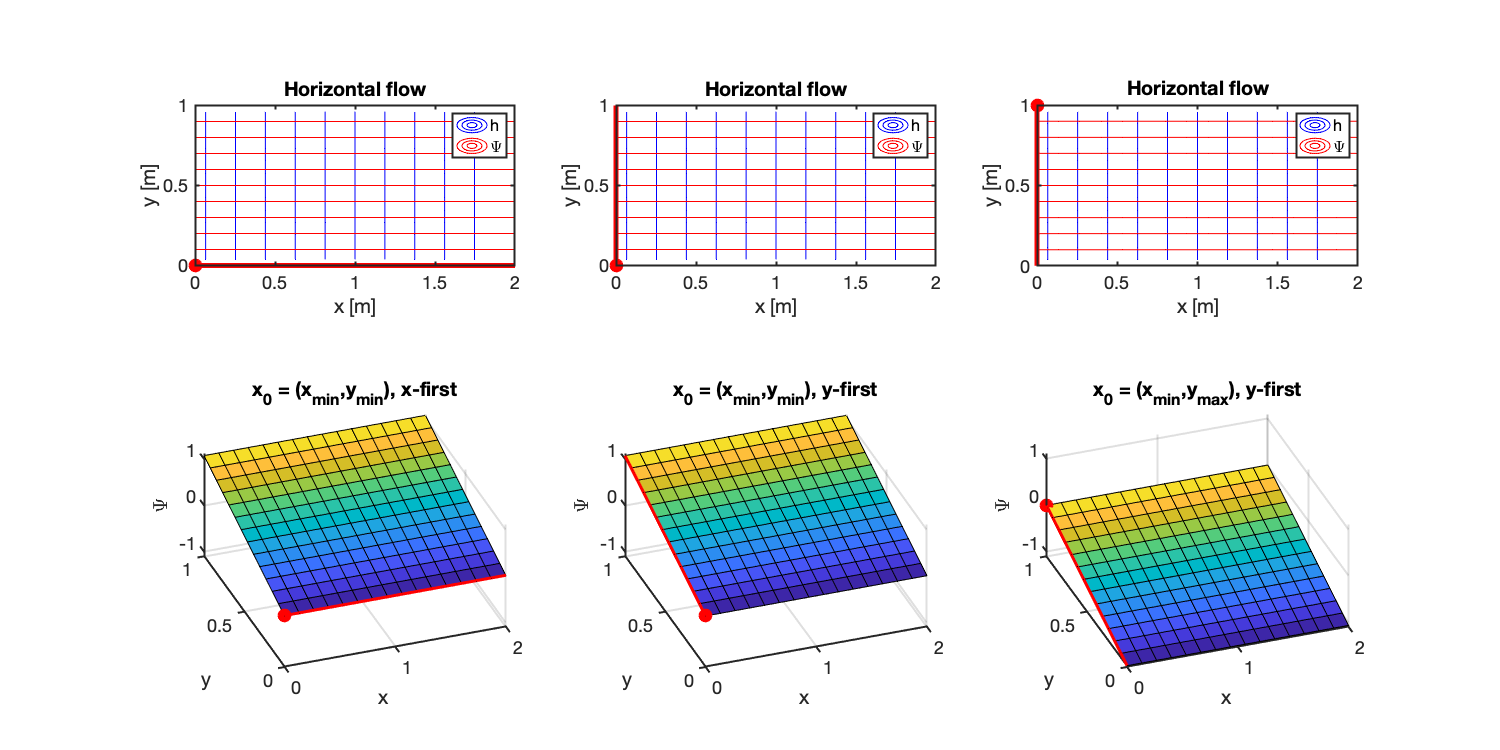

Grid.psi_x0 = 'xmin_ymin'; Grid.psi_dir = 'xy';
[PSI1, psi_min1, psi_max1] = comp_streamfun(q,Grid);

Grid.psi_x0 = 'xmin_ymin'; Grid.psi_dir = 'yx';
[PSI2, psi_min2, psi_max2] = comp_streamfun(q,Grid);

Grid.psi_x0 = 'xmin_ymax'; Grid.psi_dir = 'xy';
[PSI3, psi_min3, psi_max3] = comp_streamfun(q,Grid);


figure('position',[10 10 1500 750])
subplot 231
plot_flownet(11,11,h,PSI1,'b-','r',Grid), hold on
plot(0,0,'ro','markerfacecolor','r','markersize',12)
plot([0 Grid.xmax],[0 0],'r-','linewidth',5)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Horizontal flow'
legend('h','\Psi')

subplot 234
surf(Xp,Yp,PSI1), view(-20,30), hold on
xlabel('x'), ylabel('y'), zlabel('\Psi')
plot3(0,0,0,'ro','markerfacecolor','r','markersize',12)
plot3([0 Grid.xmax],[0 0],.01*[1 1],'r-','linewidth',3)
pbaspect([1 1 .5]), zlim([-1.1 1.1])
title('x_0 = (x_{min},y_{min}), x-first')

%%
subplot 232
plot_flownet(11,11,h,PSI2,'b-','r',Grid), hold on
plot(0,0,'ro','markerfacecolor','r','markersize',12)
plot([0 0],[0 Grid.ymax],'r-','linewidth',5)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Horizontal flow'
legend('h','\Psi')

subplot 235
surf(Xp,Yp,PSI2), view(-20,30), hold on
xlabel('x'), ylabel('y'), zlabel('\Psi')
plot3(0,0,0,'ro','markerfacecolor','r','markersize',12)
plot3(Xp(:,1),Yp(:,1),PSI2(:,1),'r-','linewidth',3)
pbaspect([1 1 .5]), zlim([-1.1 1.1])
title('x_0 = (x_{min},y_{min}), y-first')
%%
subplot 233
plot_flownet(11,11,h,PSI3,'b-','r',Grid), hold on
plot(0,1,'ro','markerfacecolor','r','markersize',12)
plot([0 0],[0 Grid.ymax],'r-','linewidth',5)
axis equal
xlabel 'x [m]', ylabel 'y [m]'
title 'Horizontal flow'
legend('h','\Psi')

subplot 236
surf(Xp,Yp,PSI3), view(-20,30), hold on
xlabel('x'), ylabel('y'), zlabel('\Psi')
plot3(Xp(Grid.Ny+1,1),Yp(Grid.Ny+1,1),PSI3(Grid.Ny+1,1),'ro','markerfacecolor','r','markersize',12)
plot3(Xp(:,1),Yp(:,1),PSI3(:,1),'r-','linewidth',3)
pbaspect([1 1 .5]), zlim([-1.1 1.1])
title('x_0 = (x_{min},y_{max}), y-first')

## Example 2: Flownets in Layered Systems

### Flow along layers

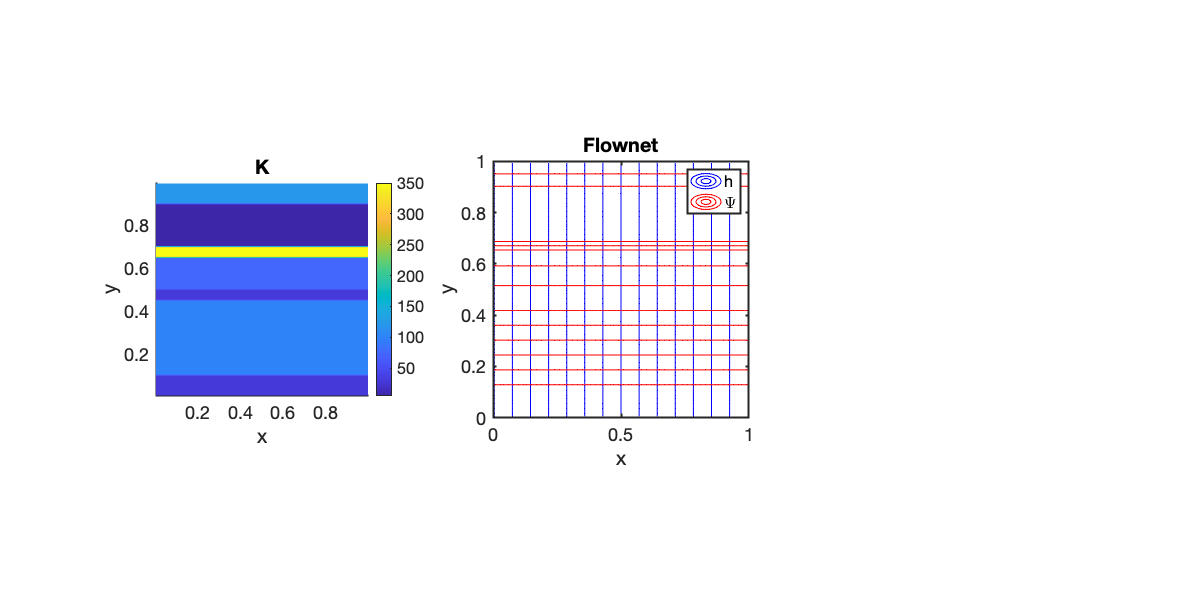

% Grid
clear Grid D G L B N I fn
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;
Grid.psi_x0 = 'xmin_ymin'; Grid.psi_dir = 'xy';
Grid = build_grid(Grid); 
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);

% Operators and conductivity
kappa_vec = [30;100;30;75;350; 5;120];
dist_vec =  [10; 35; 5;15;  5;20; 10];
[D,G,C,I,M] = build_ops(Grid);
[Kd_x,K_x] = make_layered_medium(kappa_vec,dist_vec,M,Grid,'x-dir');
L = -D*Kd_x*G; fs = zeros(Grid.N,1);

% BC's
BC.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.g         = [ones(Grid.Ny,1);zeros(Grid.Ny,1)];
BC.dof_neu   = []; BC.dof_f_neu = []; BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);


% Solve system
h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,Kd_x,G,h,fs,Grid,BC);

[PSI, psi_min1, psi_max1] = comp_streamfun(q,Grid);

figure('position',[10 10 1200 600])
subplot 131
surf(Xc,Yc,K_x), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title 'K'
axis square tight

subplot 132
plot_flownet(15,15,h,PSI,'b-','r',Grid), hold on
title 'Flownet'
axis equal
legend('h','\Psi')

### Flow across layers

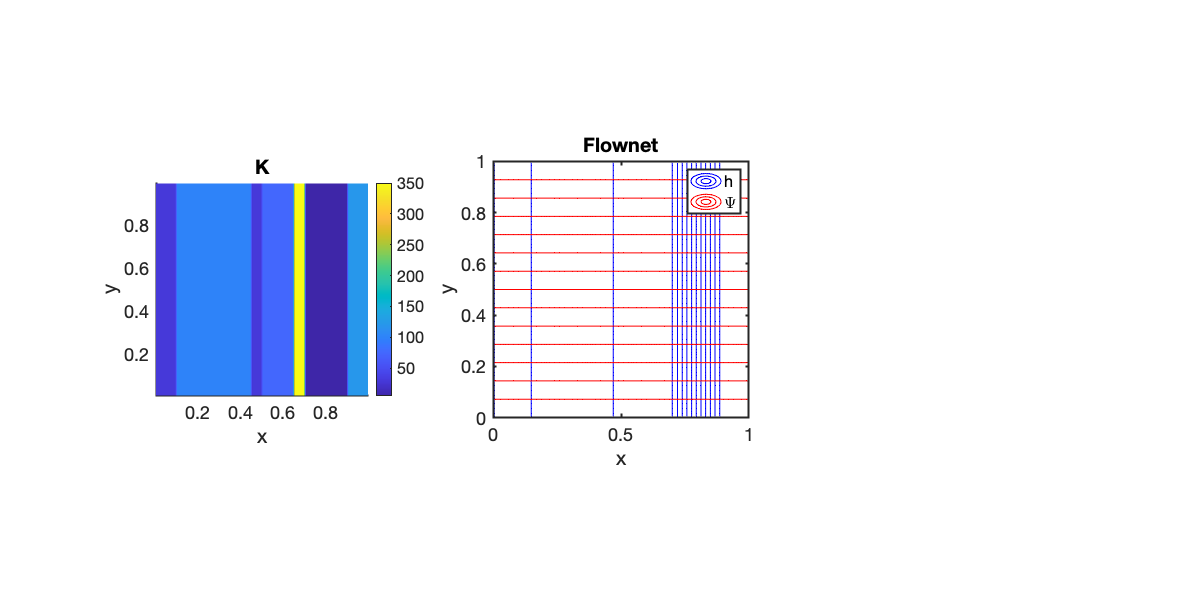

% Grid
clear Grid D G L B N I fn
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;
Grid.psi_x0 = 'xmin_ymin'; Grid.psi_dir = 'xy';
Grid = build_grid(Grid); 
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);

% Operators and conductivity
kappa_vec = [30;100;30;75;350; 5;120];
dist_vec =  [10; 35; 5;15;  5;20; 10];
[D,G,C,I,M] = build_ops(Grid);
[Kd_x,K_x] = make_layered_medium(kappa_vec,dist_vec,M,Grid,'y-dir');
L = -D*Kd_x*G; fs = zeros(Grid.N,1);

% BC's
BC.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.g         = [ones(Grid.Ny,1);zeros(Grid.Ny,1)];
BC.dof_neu   = []; BC.dof_f_neu = []; BC.qb = [];
[B,N,fn] = build_bnd(BC,Grid,I);


% Solve system
h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,Kd_x,G,h,fs,Grid,BC);

[PSI, psi_min, psi_max] = comp_streamfun(q,Grid);

figure('position',[10 10 1200 600])
subplot 131
surf(Xc,Yc,K_x), shading interp, view(2), colorbar
xlabel 'x', ylabel 'y', title 'K'
axis square tight

subplot 132
plot_flownet(15,15,h,PSI,'b-','r',Grid), hold on
title 'Flownet'
axis equal
legend('h','\Psi')

## Example 3: Heterogeneous Flownet

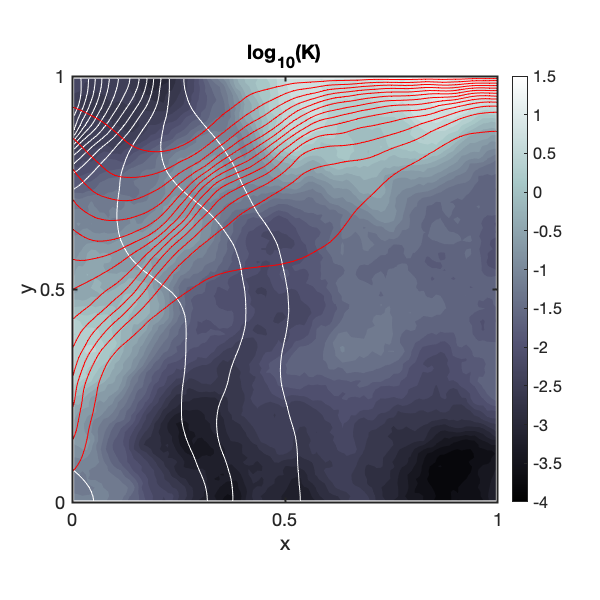

clear Grid
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;  % The only line that changes
% Grid.geom = 'cartesian';
Grid = build_grid(Grid);
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[D,G,~,I,M] = build_ops(Grid);
L = -D*G; fs = spalloc(Grid.N,1,0);

% Define the boundary conditions
BC.dof_dir   = [Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmax];
BC.g         = [zeros(Grid.Ny,1)];
BC.dof_neu   = [Grid.dof_xmin];
BC.dof_f_neu = [Grid.dof_f_xmin];
BC.qb        = ones(Grid.Ny,1);
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for head
h = solve_lbvp(L,fs+fn,B,BC.g,N);

seed = 2061972;
sigma = 0.3;
rho = 1;
[logK,gamma,delta] = comp_matern(sigma,rho,Grid,D,G,I,seed);                   
logK = reshape(logK,Grid.Ny,Grid.Nx);

K = 10.^(logK(:));
Kd = comp_mean(K,M,-1,Grid,1);
L = -D*Kd*G;

% Solve for Head
h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,Kd,G,h,fs,Grid,BC);
[PSI, psi_min, psi_max] = comp_streamfun(q,Grid);

figure('position',[10 10 600 600])
[C,h2] = contourf(Xc,Yc,logK,25); colorbar, hold on
plot_flownet(15,15,h,PSI,'w-','r',Grid),
set(h2,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
xlabel 'x', ylabel 'y', title 'log_{10}(K)'
colormap('bone'), caxis([-4 1.5])
axis equal

% [C,h3] = contourf(Xc,Yc,reshape(h,Grid.Ny,Grid.Nx),100); colorbar
% set(h3,'LineColor','none')
% set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
% axis equal
% xlabel 'x', ylabel 'y', title '2D: confined head'
% 
% figure('position',[10 10 800 500])
% subplot 121
% [C,h2] = contourf(X,Y,logK,25); colorbar
% set(h2,'LineColor','none')
% set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
% xlabel 'x', ylabel 'y', title 'log_{10}(K)'
% axis equal


## Auxillary functions

function [Kd,K] = make_layered_medium(kappa,dist,M,Grid,orientation)
if length(kappa) ~=length(dist); error('kappa and dist not same length\n'); end
K = ones(Grid.Ny,Grid.Nx); % matrix
if strcmp(orientation,'x-dir')
    K([1:dist(1)],:) = kappa(1);
    for i=2:length(kappa)
        K(sum(dist(1:i-1))+1:sum(dist(1:i)),:) = kappa(i);
    end
else
    K(:,[1:dist(1)]) = kappa(1);
    for i=2:length(kappa)
        K(:,sum(dist(1:i-1))+1:sum(dist(1:i))) = kappa(i);
    end
end
Kd = comp_mean(K(:),M,-1,Grid,1); % needs K as column vector
% Kd = comp_mean(K,-1,1,Grid);
end

function [m,gamma,delta] = comp_matern(sigma,rho,Grid,D,G,I,seed) % MDOT repo

coeff = 3.6e-07; % handcrafted, locally sourced
% 6.3441e-06 - 1 by 1 domain
% 9.7629e-06 - 2 by 2 domain
% 9.0255e-06 - 3 by 3 domain
% 8.6570e-06 - 4 by 4 domain

gamma =sqrt(coeff)/2*rho/sigma;
delta = 2*sqrt(coeff)/(rho*sigma);

L = -gamma*D*G+delta*I;
rng(seed);
fs = randn(Grid.N,1);

Param.dof_dir = [];
Param.dof_f_dir = [];
Param.g = [];
Param.dof_neu = [];
Param.dof_f_neu = [];
Param.qb = [];

[B,N,fn] = build_bnd(Param,Grid,I);
m = solve_lbvp(L,fs+fn,B,Param.g,N);
end